## Marcel Fernández - Nia 252979

## Alejandro Pastor - Nia 253563

## Problema 2

filename = '\Desktop\Models Estadistics\seminaris\entregable\SM22_LabGrades.xlsx'

filename = '\Desktop\Models Estadistics\seminaris\entregable\SM22_LabGrades.xlsx'


num = readmatrix(filename)

num =     7.3000    6.8000    6.5000    6.0000    7.7000
    7.3000    6.8000    6.5000    6.0000    7.7000
    7.5000    6.9000    7.9000    5.0000    7.9000
    7.5000    6.9000    7.9000    5.0000    7.9000
    7.0000    7.3000    4.5000    5.7000    7.1000
    4.0000    7.9000    7.9000    5.4000    6.4000
    5.0000    8.4000    5.6000    7.4000    8.6000
    5.8000    3.0000    8.6000    5.0000    5.1000
    4.2000    7.4000    8.9000    2.1000    7.6000
    4.2000    7.4000    8.9000    2.1000    7.6000


**a)  State the null and alternative hypotheses for the research question indicated at the very beginning of the problem. **						

Según lo leído en el problema, queremos evaluar si la dificultad de los laboratorios varía a lo largo del curso, así que:

- Ho: Tau_L = 0, para todos L = 1,2....,5

- Ha: Tau_L ≠ 0, for all L = 1,2....,5	

Donde Tau_L = mu_L - mu			

Es decir, que la media de cada laboratorio es la misma para todos los laboratorios (hipótesis nula).	

**b)  Propose a model to test the hypotheses stated in (a). State what assumptions are required in order to apply your model correctly.** 						

Podemos utilizar un one way ANOVA  Repeated Measures para probar las hipótesis en la parte a. Las suposiciones necesarias son las siguientes:

- **Independencia de las observaciones**: suponemos que las muestras fueron elegidas de forma independiente.

- **Normalidad univariante**

- **Esfericidad**: las varianzas de las diferencias entre todos los pares de grupos relacionados son iguales.	

**c)  Check whether your data fulfills the assumptions that you stated in (b) (use significance level α = 0.01 in your assessments). If your data does not hold the required assumptions: 							**

- **1. Check if there is a different method that could be used to solve this problem for which all the required assumptions hold. In such case, repeat (b) and (c) for that method. 						**

- **2. If the above also fails, try *****fixing *****the data with one of the suggestions from Problem 1(e). You can choose any of the options but you must retain at least 3 of the considered groups. 	**

Para comprobar todas las suposiciones, hemos realizado lo siguiente:

**Independencia de las observaciones**: Dado que no tenemos manera de verificar si los datos han sido seleccionados de manera independiente, asumimos que los datos son independientes. Sin embargo, para ser críticos, deberíamos asegurarnos de que las observaciones sean efectivamente independientes.

**Normalidad univariante**: De manera similar al ejercicio 1, realizaremos qq-plots para observar si los datos siguen una distribución normal.

**Esfericidad**: Para comprobar la esfericidad, hemos utilizado matrices de covarianza y observamos si el ratio entre las diagonales se encuentra en el intervalo deseado (1/4, 4).Es importante destacar que la corrección se centró en la gramática y la claridad del texto. Asegúrate de que el contenido y los conceptos sean precisos según el contexto en el que se esté utilizando.

First we are going to asses Univariate normality for each of the 5 groups (labs):

fprintf("qq-plot for LAB1")

qq-plot for LAB1

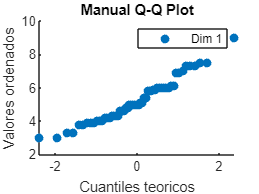

r1 = 0.9766

lab1 = num(:,1);
QQPlots(lab1) % function created in ex1 

fprintf("qq-plot for LAB2")

qq-plot for LAB2

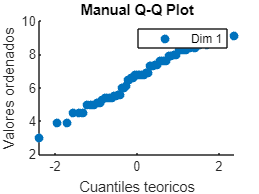

r1 = 0.9883

lab2 = num(:,2);
QQPlots(lab2)

fprintf("qq-plot for LAB4")

qq-plot for LAB4

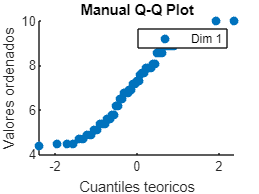

r1 = 0.9730

lab4 = num(:,3);
QQPlots(lab4)

fprintf("qq-plot for LAB5")

qq-plot for LAB5

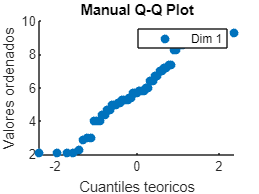

r1 = 0.9822

lab5 = num(:,4);
QQPlots(lab5)

fprintf("qq-plot for LAB6")

qq-plot for LAB6

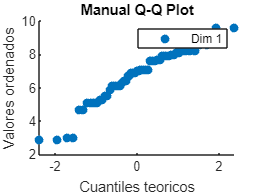

r1 = 0.9713

lab6 = num(:,5);
QQPlots(lab6)

Si observamos la tabla con un valor** alfa de 0.01** y un tamaño de muestra n = 57, en este caso vamos a ser más conservadores y vamos a elegir el valor de n = 60 porque el n = 57 no lo tenemos en la tabla, y así podemos asegurar con firmeza los resultados. Con lo cual cogemos **0.9720**

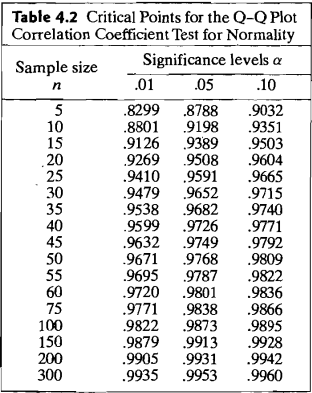

Si calculamos los coeficientes de cada qqplot podemos estudiar la normalidad, en el caso del LAB1 observamos  robs = 0.9766 > 0.9720, con lo cual podemos asumir normalidad en esta variable. De la misma manera podemos hacer comapraciones con el 'rcritic', con los otros labs, observamos que para el Lab2 -- r = 0.9883 > 0.9720, para el Lab 4 -- r = 0.9730 > 0.9720, para el lab 5 -- r = 0.9822 > 0.9720, para el último lab, Lab6 -- r = 0.9713 > 0.9720. 

Dado que todos los coeficientes son mayores que el valor crítico, podemos asumir la normalidad univariante de cada una de las calificaciones de laboratorio. 

covLab1 = cov(lab1)

covLab1 = 1.9110

covLab2 = cov(lab2)

covLab2 = 2.0679

covLab4 = cov(lab4)

covLab4 = 2.7927

covLab5 = cov(lab5)

covLab5 = 4.0954

covLab6 = cov(lab6)

covLab6 = 2.4377

Para asumir que dos varianzas son iguales, solo necesitamos asegurarnos de que 1/4 <= (var1/var2) <= 4. Como podemos ver, la mayor varianza es S5 = 4.0954 y la más pequeña es S1 = 1.911. En este caso, su división está dentro del rango establecido, por lo que podemos asumir esfericidad.

Como hemos podido observar, los datos siguen una distribución normal y las matrices de covarianza son similares. Por lo tanto, todas nuestras suposiciones se confirman, y podemos continuar con el problema.

**d)  Test the hypotheses from (a) and indicate what can you conclude about the research question, i.e. are there labs significantly more difficult than others? If so, which ones? **	

Para probar las hipótesis, primero necesitamos calcular SStreatment y SSresidual para luego calcular la  F y compararla con su valor crítico:					

g = size(num,2) %n grupos

g = 5

n = size(lab1,1)

n = 57

labs_ = sum(num)/n

labs_ =     5.2842    6.5526    7.1860    5.8316    6.6860



X_ = sum(num(:))/(n*g)

X_ = 6.3081

%SSb computation
SSb = 0;

for i=1:g
    SSb = SSb + n*((labs_(1,i)-X_)^2);
end

SSw = (lab1 - labs_(1,1))'*(lab1 - labs_(1,1)) + (lab2 - labs_(1,2))'*(lab2 - labs_(1,2)) + (lab4 - labs_(1,3))'*(lab4 - labs_(1,3)) + (lab5 - labs_(1,4))'*(lab5 - labs_(1,4)) + (lab6 - labs_(1,5))'*(lab6 - labs_(1,5));

X_subj = mean(num,2);

SSsubj = g * ((X_subj-X_)'*(X_subj-X_));

SSres = SSw - SSsubj;
MSres = SSres / ((n-1)*(g-1));
MSw = SSw/ ((n-1)*(g-1))

MSw = 3.3262

Fdalt = (SSb/(g-1));
Fbaix = ((SSw-SSsubj)/((n-1)*(g-1)));
F = Fdalt / Fbaix

F = 14.8222

alpha = 0.01;
Fcrit = finv(1-alpha,g-1,(n-1)*(g-1))

Fcrit = 3.4040

Tras hacer unos cuantos calculos podemos ver que **Fcrit < Fobs**, esto nos esta diciendo que si que existe una diferencia de grupos, entonces tenemos suficiente evidencia para rechazar la hipotesis nula. 

% All comaprisions
num_comp = g*(g-1)/2; % p = 1
alpha_new = alpha / (2*num_comp);

tcrit = tinv(1-alpha_new, n-g)

tcrit = 3.4877


% Comparisions
lab12 = abs(labs_(1)-labs_(2)) / sqrt((2/n)*MSres)

lab12 = 4.6055

lab13 = abs(labs_(1)-labs_(3)) / sqrt((2/n)*MSres)

lab13 = 6.9050

lab14 = abs(labs_(1)-labs_(4)) / sqrt((2/n)*MSres)

lab14 = 1.9874

lab15 = abs(labs_(1)-labs_(5)) / sqrt((2/n)*MSres)

lab15 = 5.0896


lab23 = abs(labs_(2)-labs_(3)) / sqrt((2/n)*MSres)

lab23 = 2.2996

lab24 = abs(labs_(2)-labs_(4)) / sqrt((2/n)*MSres)

lab24 = 2.6181

lab25 = abs(labs_(2)-labs_(5)) / sqrt((2/n)*MSres)

lab25 = 0.4841


lab34 = abs(labs_(3)-labs_(4)) / sqrt((2/n)*MSres)

lab34 = 4.9176

lab35 = abs(labs_(3)-labs_(5)) / sqrt((2/n)*MSres)

lab35 = 1.8154


lab45 = abs(labs_(4)-labs_(5)) / sqrt((2/n)*MSres)

lab45 = 3.1022

Una vez realizado el test, podemos observar que los laboratorios:

- Lab 1 vs Lab 2

- Lab 1 vs Lab 3

- Lab 1 vs Lab 5

- Lab 3 vs Lab 4

son los que tienen medias diferentes, lo que implica que tienen niveles de dificultad distintos. Para determinar cuál es más difícil, hemos calculado el valor promedio, y el laboratorio con la nota más baja se considera el más difícil. Es importante tener en cuenta que esta conclusión puede no ser totalmente precisa, ya que pueden influir otros factores.Las medias de los laboratorios son las siguientes:

- Media de Lab1 = 5.28

- Media de Lab2 = 6.55

- Media de Lab3 = 7.18

- Media de Lab4 = 5.83

- Media de Lab5 = 6.68

Por lo tanto, podemos concluir que el Laboratorio 1 es claramente el más difícil, ya que tiene la nota más baja, y, por lo tanto, es diferente de Lab2, Lab3 y Lab5 (Lab4 no se considera diferente debido a su nota media baja).Además, podemos observar que el Laboratorio 3 ha obtenido la nota más alta, lo que sugiere que ha sido el más fácil. 

**e) Compute confidence intervals for the difference of the average lab marks (for all pairs of labs). Indicate whether these intervals confirm your findings in (d). **

% Ahora hacemos todos los intervalos para confirmar los valores que hemos
% obtenido en los calculos anteriores
interval_12_neg = abs(labs_(1)-labs_(2)) - tcrit * sqrt((2/n)*MSres)

interval_12_neg = 0.3079

interval_12_pos = abs(labs_(1)-labs_(2)) + tcrit * sqrt((2/n)*MSres)

interval_12_pos = 2.2290


interval_13_neg = abs(labs_(1)-labs_(3)) - tcrit * sqrt((2/n)*MSres)

interval_13_neg = 0.9412

interval_13_pos = abs(labs_(1)-labs_(3)) + tcrit * sqrt((2/n)*MSres)

interval_13_pos = 2.8623


interval_14_neg = abs(labs_(1)-labs_(4)) - tcrit * sqrt((2/n)*MSres)

interval_14_neg = -0.4132

interval_14_pos = abs(labs_(1)-labs_(4)) + tcrit * sqrt((2/n)*MSres)

interval_14_pos = 1.5079


interval_15_neg = abs(labs_(1)-labs_(5)) - tcrit * sqrt((2/n)*MSres)

interval_15_neg = 0.4412

interval_15_pos = abs(labs_(1)-labs_(5)) + tcrit * sqrt((2/n)*MSres)

interval_15_pos = 2.3623


interval_23_neg = abs(labs_(2)-labs_(3)) - tcrit * sqrt((2/n)*MSres)

interval_23_neg = -0.3272

interval_23_pos = abs(labs_(2)-labs_(3)) + tcrit * sqrt((2/n)*MSres)

interval_23_pos = 1.5939


interval_24_neg = abs(labs_(2)-labs_(4)) - tcrit * sqrt((2/n)*MSres)

interval_24_neg = -0.2395

interval_24_pos = abs(labs_(2)-labs_(4)) + tcrit * sqrt((2/n)*MSres)

interval_24_pos = 1.6816


interval_25_neg = abs(labs_(2)-labs_(5)) - tcrit * sqrt((2/n)*MSres)

interval_25_neg = -0.8272

interval_25_pos = abs(labs_(2)-labs_(5)) + tcrit * sqrt((2/n)*MSres)

interval_25_pos = 1.0939


interval_34_neg = abs(labs_(3)-labs_(4)) - tcrit * sqrt((2/n)*MSres)

interval_34_neg = 0.3938

interval_34_pos = abs(labs_(3)-labs_(4)) + tcrit * sqrt((2/n)*MSres)

interval_34_pos = 2.3150


interval_35_neg = abs(labs_(3)-labs_(5)) - tcrit * sqrt((2/n)*MSres)

interval_35_neg = -0.4606

interval_35_pos = abs(labs_(3)-labs_(5)) + tcrit * sqrt((2/n)*MSres)

interval_35_pos = 1.4606


interval_45_neg = abs(labs_(4)-labs_(5)) - tcrit * sqrt((2/n)*MSres)

interval_45_neg = -0.1062

interval_45_pos = abs(labs_(4)-labs_(5)) + tcrit * sqrt((2/n)*MSres)

interval_45_pos = 1.8150

Podemos notar que los intervalos que **excluyen el valor 0 coinciden con las parejas que han rechazado la hipótesis nula** de medias iguales. Por lo tanto, podemos concluir que las parejas cuyos intervalos no contienen el valor 0 presentan diferencias en su dificultad.

Funciones - same as ex1 but now just one dimension

function QQPlots(d1)
    % sort dimension cols
    var = sort(d1,'ascend');
    
    n = size(var,1);
    prob = zeros(n,1);
    
    for j = 1:n
        prob(j,1) = (j-0.5)/n;
    end
    quant = norminv(prob);
    
    figure
    scatter(quant, var, 'filled');
    xlabel('Cuantiles teoricos');
    ylabel('Valores ordenados');
    legend('Dim 1');
    title('Manual Q-Q Plot');
    
    % compute correlation
    r1 = corr(var,quant)
 
end
